In the name of allah

# Linear Control Systems

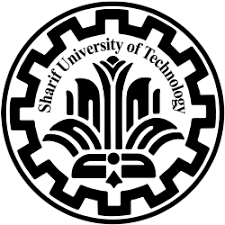

Hw 08

ali sadeghian 400101464

Fall 1402

# Theory Assignments

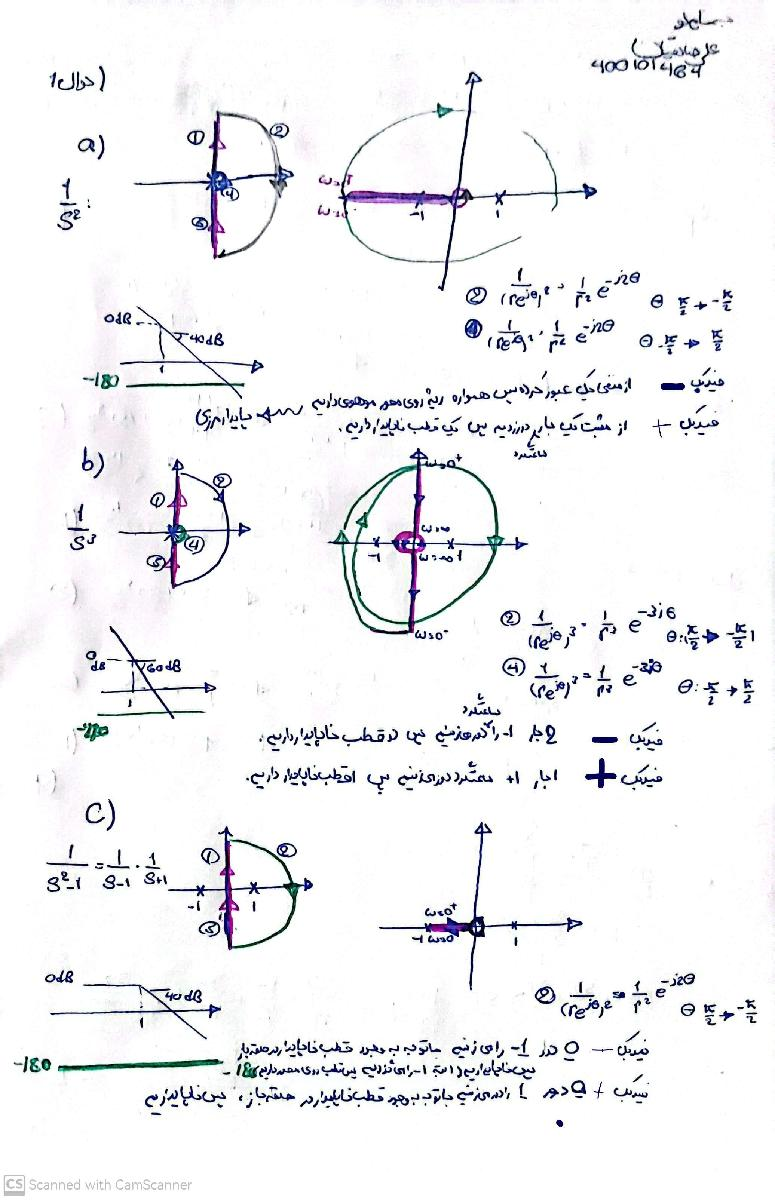

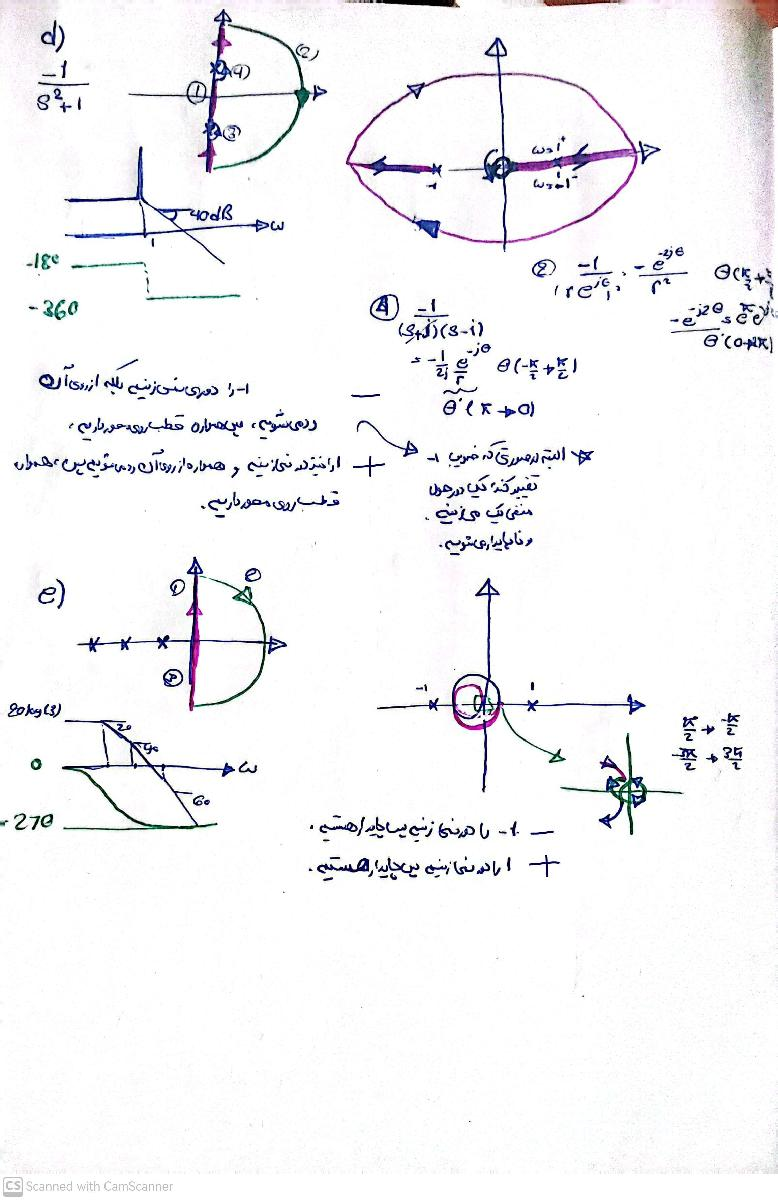

# Q2

clc
clear all
close all

## a)

The transfer function has a positive phase and gain margin , but it has an unstable pole in the unity feedback system.

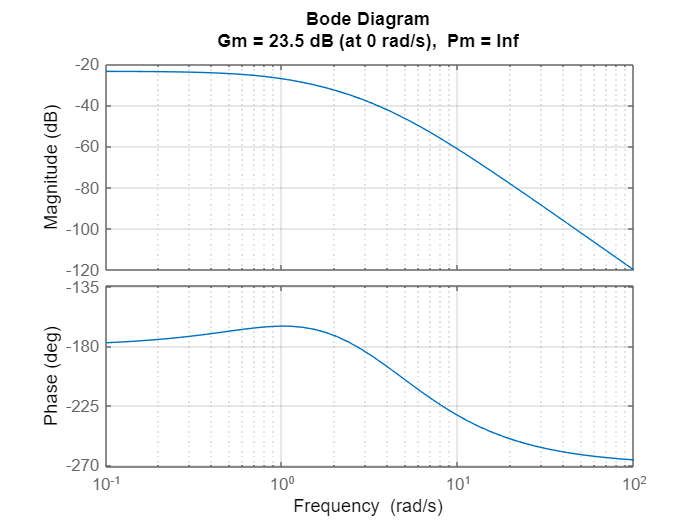

s = tf("s");
Ga = 1/(s-1)/(s+3)/(s+5);
margin(Ga)
grid on

Gfa = feedback(Ga,1);
pole(Gfa)

ans =    -5.0791
   -2.8785
    0.9576


unstable pole ( 0.9576)

## b)

The transfer function has a negative gain margin , but its unity feedback system is stable.

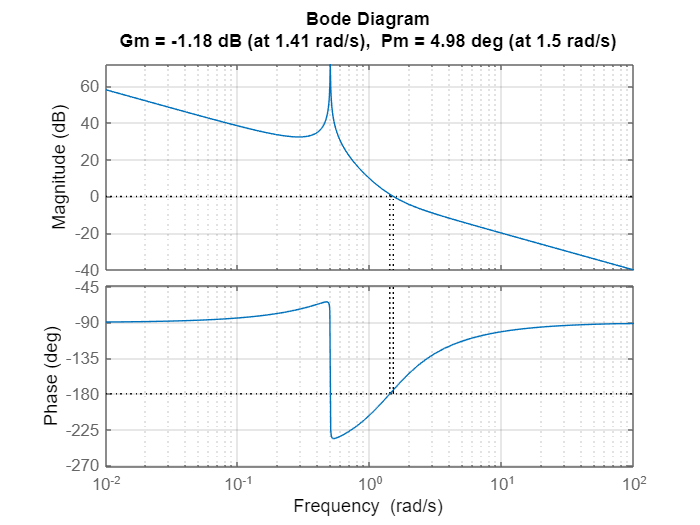

Gb = (s^2+2*s+2)/(s*(s^2+0.002*s+0.25));
margin(Gb)
grid on

Gfb = feedback(Gb,1);
pole(Gfb)

ans =   -0.0411 + 1.4740i
  -0.0411 - 1.4740i
  -0.9198 + 0.0000i


zero(Gfb)

ans =   -1.0000 + 1.0000i
  -1.0000 - 1.0000i


no unstable zero or poles exist.

## c)

People are interested in guaranteeing closed-loop stability by designing a controller with positive margins because it is a conservative approach that provides a safety margin. Positive margins refer to having a gain margin and phase margin greater than zero.

This method typically works because positive margins indicate that the system is robust and less sensitive to parameter variations or disturbances. It means that the system can tolerate some level of uncertainty without destabilizing. 

While positive margins are not necessary or sufficient to guarantee closed-loop stability, they do provide an indication of the system's stability and performance. By designing the controller with positive margins, engineers can ensure that the system will remain stable even in the presence of uncertainties or disturbances. It offers a buffer against potential instabilities, ensuring a more reliable and robust closed-loop system.

However, there are several reasons why designing a controller to provide positive margins is a common and often effective approach:

- Simple Assessment of Robustness: Gain and phase margins give an immediate and easy-to-understand measure of the system’s robustness to gain variations and phase lags. A system with generous positive margins is generally less sensitive to model uncertainties and parameter changes.

- Heuristic Success: Historically, control systems were designed with these margins positive to ensure stability, and in practice, it has been found to work well for a wide range of systems. Although there can be exceptions, positive margins have emerged as a rule-of-thumb because they usually produce good results.

- Practicality in Linear Systems: For many linear, time-invariant systems, positive margins are satisfactory for ensuring stability. Many systems can indeed be approximated reasonably well as linear and time-invariant over the operating range of interest.

- Frequency Domain Analysis: Tools like Bode plots are particularly insightful for frequency-domain analysis. They provide a visual means to understand system behavior over a range of frequencies while revealing information about resonant frequencies, gain crossover frequency, and phase crossover frequency, which all contribute to the design and analysis of stable control systems.

- Engineering Design Goals: In control system engineering, the goal is not only to achieve stability but also to achieve desirable transient response characteristics(like overshoot, rise time, settling time), and steady-state performance (like steady-state error). Positive margins help achieve these goals.

- Predicted Response to External Disturbances: Systems with adequate phase margins typically exhibit better performance in the presence of external disturbances or noise. They tend to have smoother transient responses and less oscillatory behavior.

- Nyquist Stability Criterion Compliance: A positive gain margin and phase margin typically mean that the Nyquist plot doesn’t encircle the critical point of -1, indicating stability for minimum phase systems (systems without right-half-plane zeros or poles).

- Intuitive Tuning: Tuning controllers to achieve desired margins can be more intuitive than directly shaping the root locus or dealing with more complex approaches, making the process accessible to a broader range of engineers.

Nevertheless, there are cases where maintaining positive margins may not be the best strategy, such as in systems requiring high-speed performance, where a control strategy called “Critical Damping” or “Bang-Bang Control” may be more appropriate. Additionally, in advanced control techniques like H-infinity control or Quantitative Feedback Theory (QFT), robust stability and performance are framed differently, not relying solely on classical margins.

In cross-disciplinary and complex systems, it’s common to go beyond simple gain and phase margins and use more advanced analysis and design tools. However, for most traditional linear control problems, the method of designing for positive gain and phase margins is a well-established starting point that typically provides good initial results and serves as the foundation for further system refinement.

## d)

No, a Bode plot does not contain all equivalent information that is contained in a Nyquist plot. While both plots are derived from the same open-loop transfer function and can be used to assess system stability, they offer different insights. Here’s why:

Nature of Plots:

- Bode Plot: It is a logarithmic plot that separately graphs the magnitude (in decibels) and phase (in degrees) of the system’s frequency response as a function of frequency. The frequency is considered along the X-axis on a logarithmic scale.

- Nyquist Plot: It is a polar plot that maps the complex-valued frequency response of the system, ( $ G(j\omega)H(j\omega)$), where the real and imaginary parts of the frequency response are plotted against each other for a range of frequencies from (0) to (∞).

Stability Information:

- A Bode plot can be used to infer stability through gain and phase margin measurements. However, it does not show the full closed-loop frequency response. This means that while positive gain and phase margins indicate a tendency toward stability, they do not guarantee it, especially in systems with significant delays or non-minimum phase behavior.

- A Nyquist plot can be used to assess stability directly for a closed-loop system using the Nyquist stability criterion, which accounts for the number of encirclements of the critical point ((-1 + 0j)).

Time Delays and Non-Minimum Phase Behavior:

- A Bode plot can suggest potential stability issues due to time delays and non-minimum phase behavior, but it cannot fully represent the effects because it only shows amplitude and phase at the frequency points plotted.

- A Nyquist plot includes the full mapping of the complex plane and thus inherently includes the effects of time delays and non-minimum phase elements through the argument principle.

Encirclements:

- In a Bode plot, you cannot see the number of encirclements around the critical point, which is essential for systems with poles on the right-half s-plane when applying the Nyquist stability criterion.

- The Nyquist plot directly shows these encirclements, which can diagnose the stability of such difficult systems.

Use Cases:

- Bode plots are widely used for designs using frequency response techniques and are particularly helpful in controller tuning (such as PID tuning) and gain/phase margin optimization for robust control.

- Nyquist plots are essential for a comprehensive stability analysis, especially when dealing with complex poles and zeros and non-minimum phase systems, which might be misleading in a Bode plot.

In summary, while the Bode plot provides a good understanding of the system behavior in the frequency domain and is useful for the design and tuning of controllers, the Nyquist plot offers a more comprehensive stability analysis by depicting how the complex gain encircles key points in the complex plane. The two are complementary, and in the practice of control system analysis and design, it is often valuable to consider both for a complete picture of system behavior.

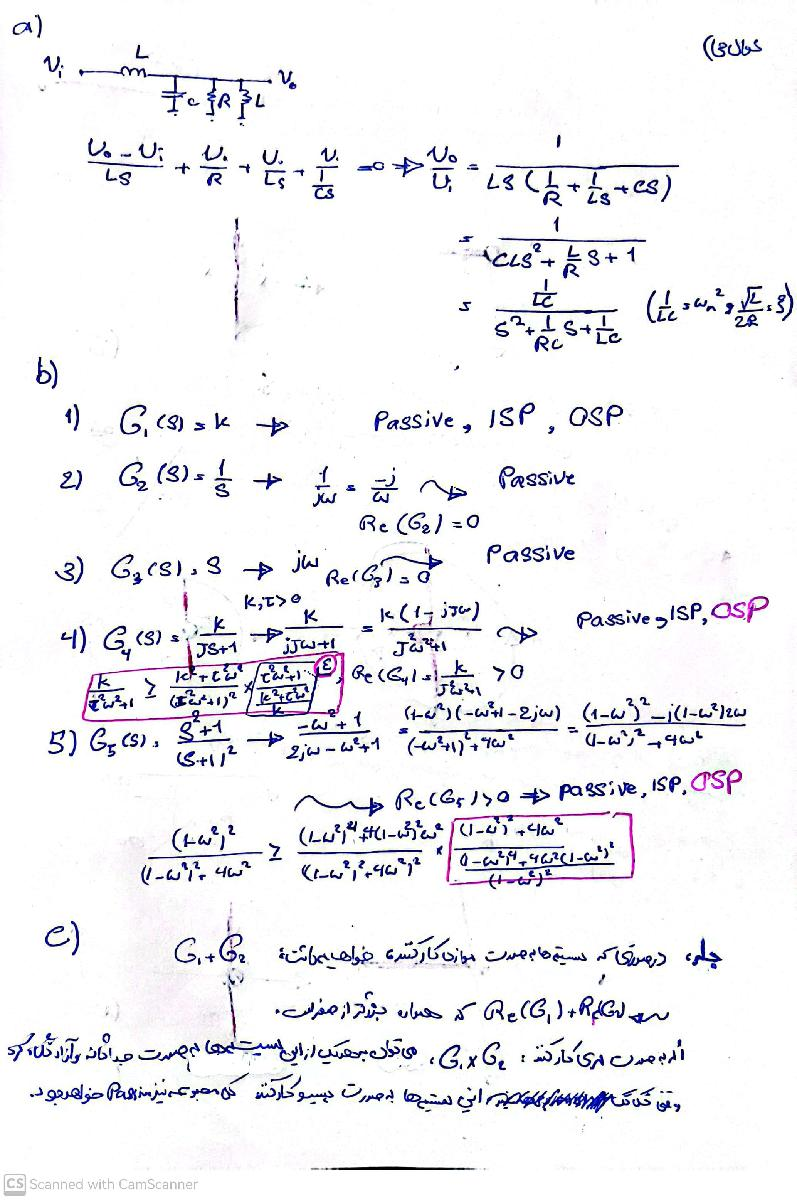

# Q4

## a)

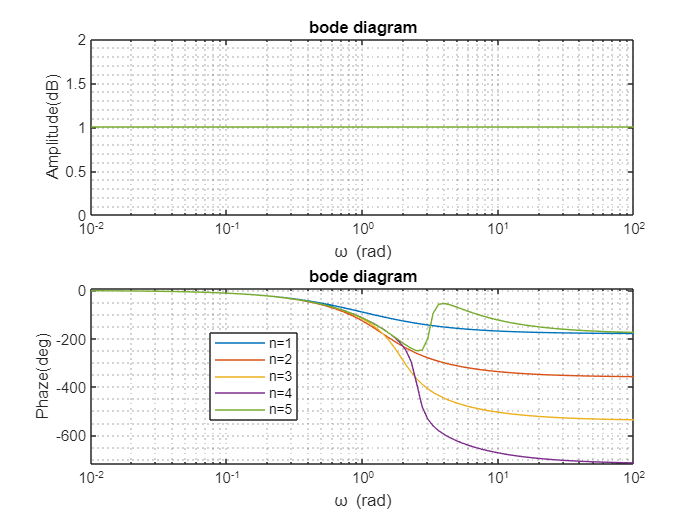

s = tf("s");
T = 2;
G1 = (1-s)/(1+s);
G2 = (2-2*s+s^2)/(2+2*s+s^2);
G3 = (6-6*s+3*s^2-s^3 )/(6+6*s+3*s^2+s^3);
G4 = (24-24*s+12*s^2-4*s^3+s^4)/(24+24*s+12*s^2+4*s^3+s^4);
G5 = (120-120*s+60*s^2-20*s^3+5*s^4-s^5)/(120+120*s+60*s^2+20*s^3+5*s^4+s^5);
Wout = logspace(-2,2,101);
[mag1,phase1] = bode(G1,Wout);
[mag2,phase2] = bode(G2,Wout);
[mag3,phase3] = bode(G3,Wout);
[mag4,phase4] = bode(G4,Wout);
[mag5,phase5] = bode(G5,Wout);
phase11 = zeros([2 101]);
phase22 = zeros([2 101]);
phase33 = zeros([2 101]);
phase44 = zeros([2 101]);
phase55 = zeros([2 101]);
for i=1:101
    phase11(1,i) = phase1(1,1,i)-360;
    phase22(1,i) = phase2(1,1,i)-360;
    phase33(1,i) = phase3(1,1,i)-720;
    phase44(1,i) = phase4(1,1,i)-720;
    phase55(1,i) = phase5(1,1,i)-360;
    phase11(2,i) = mag1(1,1,i);
    phase22(2,i) = mag2(1,1,i);
    phase33(2,i) = mag3(1,1,i);
    phase44(2,i) = mag4(1,1,i);
    phase55(2,i) = mag5(1,1,i);
end
subplot(2,1,1)
semilogx(Wout,phase11(2,:),Wout,phase22(2,:),Wout,phase33(2,:),Wout,phase44(2,:),Wout,phase55(2,:))
ylabel("Amplitude(dB)")
xlabel("\omega (rad)")
title("bode diagram")
grid minor
subplot(2,1,2)
semilogx(Wout,phase11(1,:),Wout,phase22(1,:),Wout,phase33(1,:),Wout,phase44(1,:),Wout,phase55(1,:))
ylim([-720 10])
ylabel("Phaze(deg)")
xlabel("\omega (rad)")
title("bode diagram")
grid minor
legend("n=1","n=2","n=3","n=4","n=5",'Location','best')

As we can see, with the increase of order, improvement occurs in low frequencies, but in high frequencies ,Approximation cannot follow well.

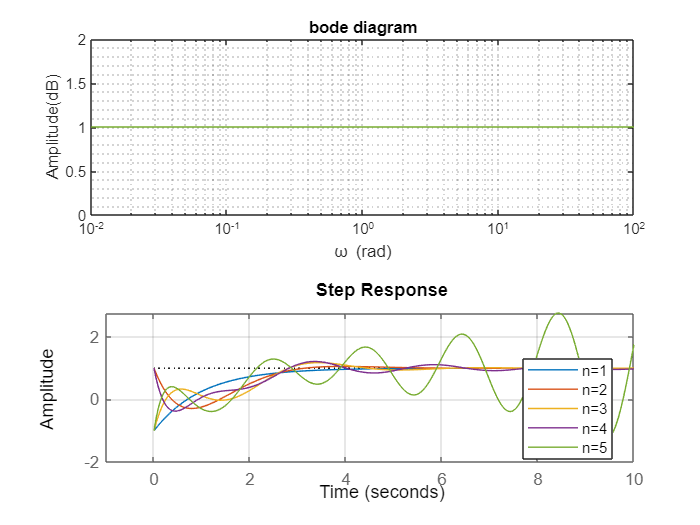

step(G1,G2,G3,G4,G5)
grid minor
xlim([-1,10])
legend("n=1","n=2","n=3","n=4","n=5",'Location','best')

The step response has a jump at the beginning, and as the approximation order increases, the oscillations become more intense and the system becomes more unstable.

## c)

as we see, it isn't stable.

## d)


$$\begin{array}{l}
\frac{1+p_1 \textrm{Ts}}{1+q_1 \textrm{Ts}}=1+\left(p_{1\;} -q_1 \right)\textrm{Ts}+\left(q_1^2 -q_1 p_1 \right){T^2 s}^2 =1-\textrm{sT}+{0\ldotp 5\left(\textrm{sT}\right)}^2 \Rightarrow p_{1\;} -q_1 =-1,q_1^2 -q_1 p_1 =0\ldotp 5\\
\Rightarrow q_1 =0\ldotp 5,p_{1\;} =-0\ldotp 5
\end{array}$$


## e)


$$\begin{array}{l}
\frac{1+p_1 s+p_2 s^2 }{1+q_1 s+q_2 s^2 }=1+\left(p_{1\;} -q_1 \right)\textrm{Ts}+\left(q_1^2 -q_1 p_1 \right){T^2 s}^2 +{\left(\ldotp \ldotp \ldotp \right)\left(\textrm{sT}\right)}^3 +{\left(\ldotp \ldotp \ldotp \right)\left(\textrm{sT}\right)}^4 =1-\textrm{sT}+{\frac{1}{2}{\left(\textrm{sT}\right)}^2 } +\frac{1}{6}{\left(\textrm{sT}\right)}^3 +\frac{1}{24}{\left(\textrm{sT}\right)}^4 \\
\Rightarrow q_1 =\frac{1}{2},p_{1\;} =-\frac{1}{2},q_2 =\frac{1}{12},p_2 =\frac{1}{12}\;
\end{array}$$


In the first stage, yes, but in the second stage, they are different.

syms x
expr = exp(-x);
pade(expr,'Order',2)

$$ans = \frac{x^{2}-6\,x+12}{x^{2}+6\,x+12}$$

we have a jump at time $t=0$ in step response:


$$\lim_{s\longrightarrow \infty } s\frac{\sum_0^N p_i s^i }{\sum_0^N q_i s^i }\frac{1}{s}\;=\lim_{s\longrightarrow \infty } \;\frac{p_N }{q_N }\not= 0\Rightarrow \textrm{we}\;\textrm{have}\;\textrm{jump}\;\textrm{at}\;t=0\;$$


## f)

T = 2;
[num, den] = pade(T, 1);
Gpade1 = tf(num, den);
[num, den] = pade(T, 2);
Gpade2 = tf(num, den);
[num, den] = pade(T, 3);
Gpade3 = tf(num, den);
[num, den] = pade(T, 4);
Gpade4 = tf(num, den);
[num, den] = pade(T, 5);
Gpade5 = tf(num, den);
Wout = logspace(-2,2,101);
[mag1,phase1] = bode(Gpade1,Wout);
[mag2,phase2] = bode(Gpade2,Wout);
[mag3,phase3] = bode(Gpade3,Wout);
[mag4,phase4] = bode(Gpade4,Wout);
[mag5,phase5] = bode(Gpade5,Wout);
phase11 = zeros([2 101]);
phase22 = zeros([2 101]);
phase33 = zeros([2 101]);
phase44 = zeros([2 101]);
phase55 = zeros([2 101]);
for i=1:101
    phase11(1,i) = phase1(1,1,i)-360;
    phase22(1,i) = phase2(1,1,i)-360;
    phase33(1,i) = phase3(1,1,i)-720;
    phase44(1,i) = phase4(1,1,i)-720;
    phase55(1,i) = phase5(1,1,i)-1080;
    phase11(2,i) = mag1(1,1,i);
    phase22(2,i) = mag2(1,1,i);
    phase33(2,i) = mag3(1,1,i);
    phase44(2,i) = mag4(1,1,i);
    phase55(2,i) = mag5(1,1,i);
end
subplot(2,1,1)
semilogx(Wout,phase11(2,:),Wout,phase22(2,:),Wout,phase33(2,:),Wout,phase44(2,:),Wout,phase55(2,:))
ylabel("Amplitude(dB)")
xlabel("\omega (rad)")
title("bode diagram")
grid minor

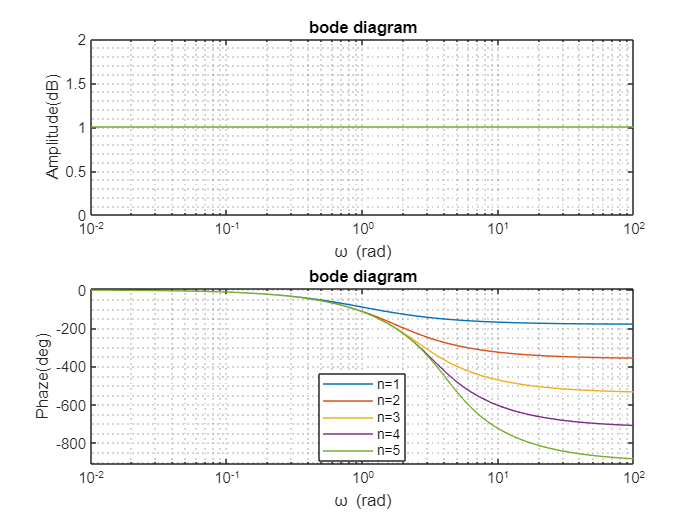

subplot(2,1,2)
semilogx(Wout,phase11(1,:),Wout,phase22(1,:),Wout,phase33(1,:),Wout,phase44(1,:),Wout,phase55(1,:))
ylim([-910 10])
ylabel("Phaze(deg)")
xlabel("\omega (rad)")
title("bode diagram")
grid minor
legend("n=1","n=2","n=3","n=4","n=5",'Location','best')

The higher the approximation order, the more bandwidth is covered by this approximation.

## g)

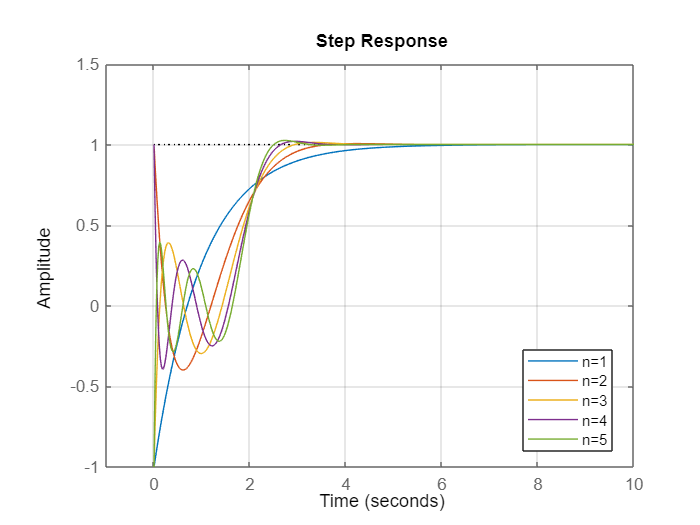

figure
step(Gpade1,Gpade2,Gpade3,Gpade4,Gpade5)
grid minor
xlim([-1,10])
legend("n=1","n=2","n=3","n=4","n=5",'Location','best')

The step response has a jump at the beginning,and as the order of approximation increases, the answer converges faster.

## h)

syms x
T = 2;
expr = exp(-T*x);

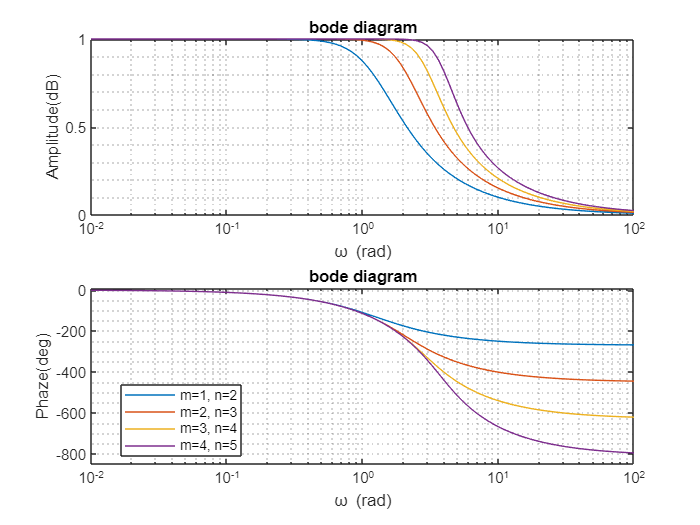

[num, den]= numden(pade(expr,'Order',[1 2]));
num = eval(coeffs(num));
den = eval(coeffs(den));
Gpade1 = tf(flip(num),flip(den));
[num, den]= numden(pade(expr,'Order',[2 3]));
num = eval(coeffs(num));
den = eval(coeffs(den));
Gpade2 = tf(flip(num),flip(den));
[num, den]= numden(pade(expr,'Order',[3 4]));
num = eval(coeffs(num));
den = eval(coeffs(den));
Gpade3 = tf(flip(num),flip(den));
[num, den]= numden(pade(expr,'Order',[4 5]));
num = eval(coeffs(num));
den = eval(coeffs(den));
Gpade4 = tf(flip(num),flip(den));

Wout = logspace(-2,2,101);
[mag1,phase1] = bode(Gpade1,Wout);
[mag2,phase2] = bode(Gpade2,Wout);
[mag3,phase3] = bode(Gpade3,Wout);
[mag4,phase4] = bode(Gpade4,Wout);

phase11 = zeros([2 101]);
phase22 = zeros([2 101]);
phase33 = zeros([2 101]);
phase44 = zeros([2 101]);

for i=1:101
    phase11(1,i) = phase1(1,1,i)-360;
    phase22(1,i) = phase2(1,1,i)-360;
    phase33(1,i) = phase3(1,1,i)-720;
    phase44(1,i) = phase4(1,1,i)-720;
    phase11(2,i) = mag1(1,1,i);
    phase22(2,i) = mag2(1,1,i);
    phase33(2,i) = mag3(1,1,i);
    phase44(2,i) = mag4(1,1,i);
end
subplot(2,1,1)
semilogx(Wout,phase11(2,:),Wout,phase22(2,:),Wout,phase33(2,:),Wout,phase44(2,:))
ylabel("Amplitude(dB)")
xlabel("\omega (rad)")
title("bode diagram")
grid minor
subplot(2,1,2)
semilogx(Wout,phase11(1,:),Wout,phase22(1,:),Wout,phase33(1,:),Wout,phase44(1,:))
ylim([-850 10])
ylabel("Phaze(deg)")
xlabel("\omega (rad)")
title("bode diagram")
grid minor
legend("m=1, n=2","m=2, n=3","m=3, n=4","m=4, n=5",'Location','best')

The higher the approximation order, the more bandwidth is covered by this approximation.Also, the amplitude starts to decrease from the cutoff frequency

## i)

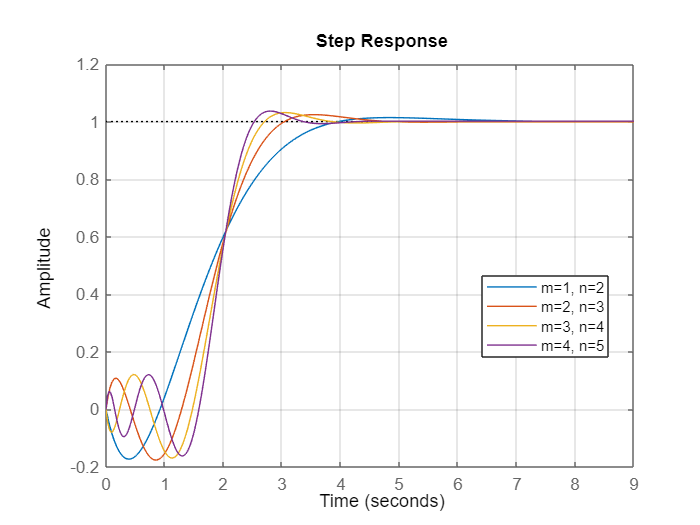

figure
step(Gpade1,Gpade2,Gpade3,Gpade4)
grid minor
legend("m=1, n=2","m=2, n=3","m=3, n=4","m=4, n=5",'Location','best')

The response does not jump at first, and with increasing order of approximation, faster and better behavior is observed

## j)

The use of Padé approximations with equal-degree numerator and denominator in frequency domain analysis, and a lower degree numerator than denominator in time domain analysis, can be understood by looking at their impact on the system's stability and the accuracy of approximation in different domains.

1. Equal Degree (Frequency Domain Analysis):

   - In frequency domain analysis, particularly in control systems, it is often desired to preserve the phase characteristics of the system. Equal-degree Padé approximators tend to be well-balanced in this regard, approximating the time delay without excessively altering the phase margin.

   - In designing feedback controls, it's crucial to obtain accurate phase information to ensure stability and proper transient response; thus the symmetry in the order of the approximation is preferred.

   - Equal-degree Padé approximations offer a reasonable compromise between time delay representation (phase delay) and the complexity of the transfer function in both the amplitude and phase plots in the Bode diagram.

2. Lower Degree Numerator (Time Domain Analysis):

   - For the time domain analysis, particularly concerning step responses or transient behaviors, lower-degree numerators are often used because they tend to avoid introducing non-minimum phase zeros that can cause an initial response in the opposite direction of the final value (a negative initial kick in the response).

   - A lower-order numerator in the Padé approximation will usually result in a transfer function that has a more stable step response, as it introduces fewer oscillatory modes or high-frequency components that could lead to instability or unrealistic behavior in the time domain.

   - The approximation in the time domain does not focus on the phase information as much as it does in the frequency domain; hence, it is more important to maintain the characteristics of the system's transient response.

In summary, the difference in the orders of the numerator and denominator in Padé approximations for frequency vs. time domain analysis boils down to aligning with the respective priorities of each domain: phase accuracy for frequency response and avoiding negative response behavior for time response. The particular choice of Padé approximation degree can also be influenced by other factors in a given system, such as the allowable computational complexity, desired accuracy, and the specific application (e.g., stability concerns in the analysis of control systems).

# MATLAB Assignment

# Q5 Root-locus of time Delayed System

## a)


$$\begin{array}{l}
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;L\left(s\right)=\frac{e^{-\textrm{Ts}} }{s+p}\Rightarrow \frac{K\ldotp L\left(s\right)}{1+K\ldotp L\left(s\right)}=\frac{{K\ldotp e}^{-\textrm{Ts}} }{s+p+Ke^{-\textrm{Ts}} }\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;s+p+{\textrm{Ke}}^{-\textrm{Ts}} =0\Rightarrow \;e^{-\textrm{Ts}} =\;\frac{s+P}{-K}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Rightarrow \textrm{Ts}=\ln \left(-\frac{K}{s+p}\right)
\end{array}$$


## b)

As we can see, the solve function cannot find more than one answer, that's why we use the fsolve function, which gives different answers with a different initial value.

    solve function

syms x;
T = 0.1;
p =  2;
K = 9;
eqn = x+p+K*exp(-T*x) == 0 ;
sol = solve(eqn, x);
var = double(sol)

var = -4.5199 + 13.9166i

        fsolve function

K = 9;
eqn = @(x) x + p + K * exp(-T * x);

% Set options for the `fsolve` function
options = optimoptions('fsolve', 'Display', 'off', 'Algorithm', 'levenberg-marquardt');

% Initial guess for the solution(s)
x0 = [-0.1+2i -0.1-2i -10+20i -10-20i -50+20i -50-20i];

% Solve the equation using `fsolve`
[x, fval, exitflag] = fsolve(eqn, x0, options);
double(x)

ans =   -4.5199 +13.9166i  -4.5199 -13.9166i  -4.5199 +13.9166i  -4.5199 -13.9166i  -4.5199 +13.9166i  -4.5199 -13.9166i


        pade approximations in solve function

syms x;
T = 0.1;
p =  2;
K = 9;

[num, den] = pade(T,5);
mypade = poly2sym(num, x)/ poly2sym(den, x);
eqn =  x + p + K * mypade == 0;
sol = solve(eqn, x);
var = double(sol)

var = 	1.0e+02 *

  -0.0452 - 0.1392i
  -0.0452 + 0.1392i
  -0.2295 - 0.7461i
  -0.2295 + 0.7461i
  -1.1903 - 1.0645i
  -1.1903 + 1.0645i


## c & d)

               solve

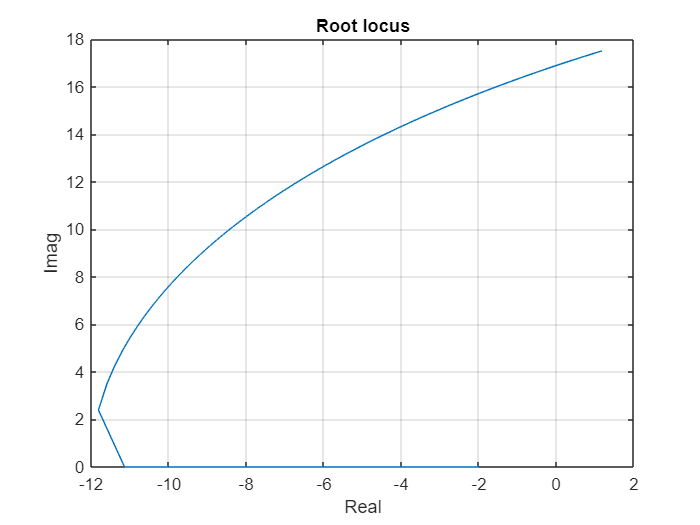

syms x;
T = 0.1;
p =  2;
eqn = x+p+K*exp(-T*x) == 0 ;
K = 0:0.1:20;
S = zeros(size(K));
for i=1:size(K,2)
    eqn = x+p+K(i)*exp(-T*x) == 0 ; 
    S(i) = eval(solve(eqn,x));
end
figure
plot(S)
xlabel("Real")
ylabel("Imag")
title("Root locus")
grid on

        fsolve

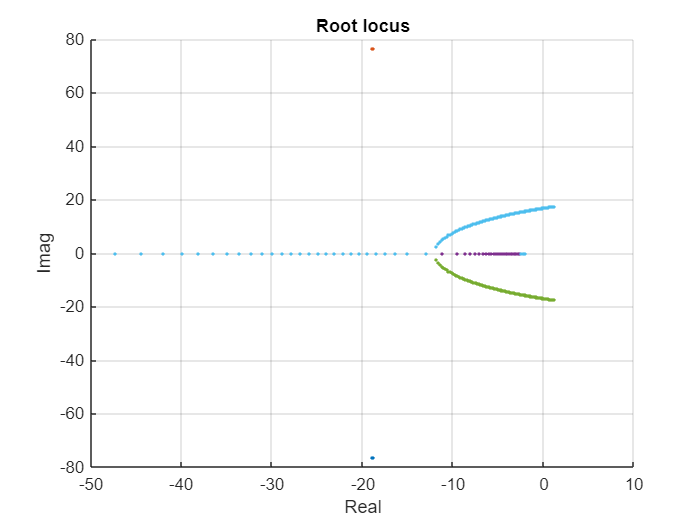

options = optimoptions('fsolve', 'Display', 'off', 'Algorithm', 'levenberg-marquardt');
x0 = [-0.1+2i -0.1-2i -10+10i -10-10i -50+20i -50-20i];
T = 0.1;
p =  2;
K = 0:0.1:20;
S2 = zeros([size(K,2) size(x0,2)]);
for i=1:size(K,2)
    eqn = @(x) x + p + K(i) * exp(-T * x); 
    [x, fval, exitflag] = fsolve(eqn, x0, options);
    S2(i,:) = double(x)';
end

figure
scatter(real(S2),imag(S2),".")
xlabel("Real")
ylabel("Imag")
title("Root locus")
grid on

## e)

[~, index] = min(abs(real(S)));
S(index)

ans = -0.0021 + 16.8857i

Ki = K(index)

Ki = 17

## f)

Since we have the pole on an imaginary axis, we expect to pass through the point (-1,0).

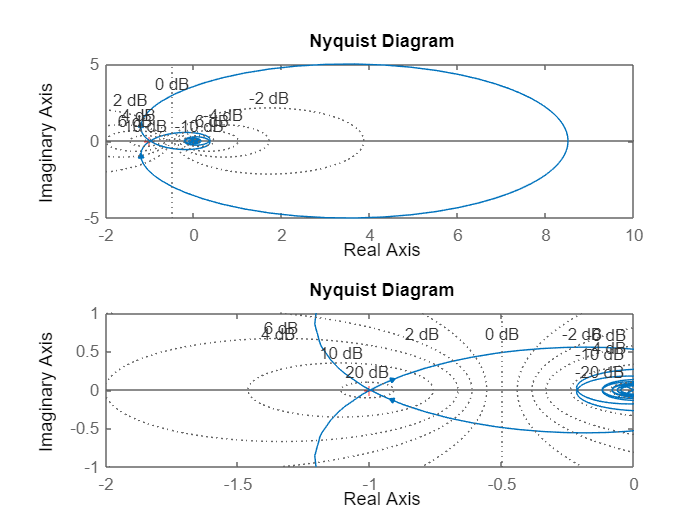

s = tf("s");
sys = Ki * exp(-T*s)/(s+p);
figure
subplot(2,1,1)
nyquist(sys)
grid on
subplot(2,1,2)
nyquist(sys)
grid on
xlim([-2 0])
ylim([-1 1])

As we can see, we cross over (-1,0).

## g)

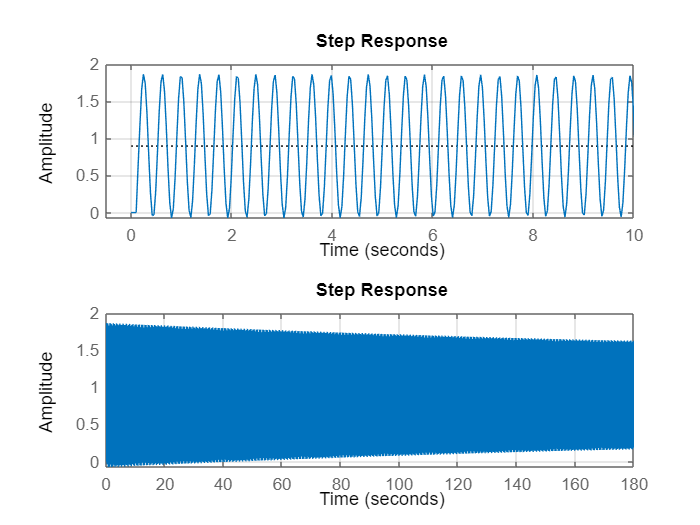

sysf = feedback(sys,1);
figure
subplot(2,1,1)
step(sysf)
grid on
xlim([-0.5 10])
subplot(2,1,2)
step(sysf)
grid on

As we can see, the system transient state is very high and it looks like a sinusoid response.